# Creating Filters in Swan

## Introduction

In these tutorial files, you will learn how to use the various modules of Swan in order to generate your own FEM and Topology Optimization simulations. In each tutorial, a single building block will be analyzed, with some examples to make it easier. If you have any questions, feel free to create a new issue in the GitHub repository.

## Preliminars

In this tutorial we will deal with Filters, which are crucial tools to control the *gray* regions of density fields or avoid checkerboarding problems during simulations. Given any function defined on our domain, Filters basically build a Finite Element Function based in the input function and smoothing it.

Before starting bulding our own filters, let's begin with some preliminars. First, we need a mesh on which the *given* (or input) function will be filtered. Consider the following discretization of a [0,1]x[0,1] domain (Figure 1):

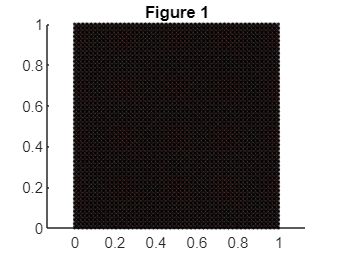

clear;
close all;

x1      = linspace(0,1,50);
x2      = linspace(0,1,50);
[xv,yv] = meshgrid(x1,x2);
[F,V]   = mesh2tri(xv,yv,zeros(size(xv)),'x');

m.coord  = V(:,1:2);
m.connec = F;
mesh     = Mesh.create(m);

figure()
mesh.plot()
title('Figure 1')

Moreover, we need a *given *function. As a first example, we are going to create a Characteristic Function, which will be defined on previous [0,1]x[0,1] domain. First as an analytical function:

s.fHandle = @(x) 1-heaviside((x(1,:,:)-0.5).^2+(x(2,:,:)-0.5).^2-0.3.^2);
s.ndimf   = 1;
s.mesh    = mesh;
fun       = AnalyticalFunction(s);

Let's also create the same function defined on an unfitted mesh, using a geometrical function:

gPar.type        = 'Circle';
gPar.radius      = 0.3;
gPar.xCoorCenter = 0.5;
gPar.yCoorCenter = 0.5;
g                = GeometricalFunction(gPar);
phiFun           = g.computeLevelSetFunction(mesh);
phi              = phiFun.fValues;

sUm.backgroundMesh = mesh;
sUm.boundaryMesh   = mesh.createBoundaryMesh;
uMesh              = UnfittedMesh(sUm);
uMesh.compute(phi);

funLS     = CharacteristicFunction.create(uMesh);

Previous given functions return 0 everywhere except on a disc of height z=1, centered on (0.5,0.5) and radius 0.3. We can see how this characteristic function would look like by projecting it to a P0 FE function (Figure 2):

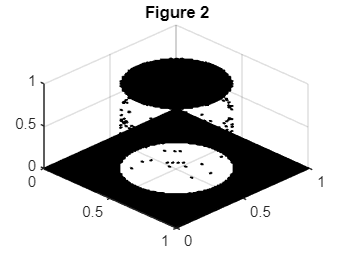

fP0 = fun.project('P0');
fP0.plot()
view(45,45)
title('Figure 2')

## Filters

### P1 Filter

Let's start now creating our first filter: P1. This is formally known as Kernel filter. The operator basically computes an average field, using as reference the patch formed by the degrees of freedom stated in the test function, and expressing the final result in the vectorial base of the trial function. Consider, for instance, a P0 to P1 Kernel filter:

ss.filterType = 'P1';
ss.mesh       = mesh;
ss.test       = LagrangianFunction.create(mesh,1,'P0');
ss.trial      = LagrangianFunction.create(mesh,1,'P1');
filter        = Filter.create(ss);

Now, we can obtain our first filtered function of the characteristic function by means of the following filter public command:

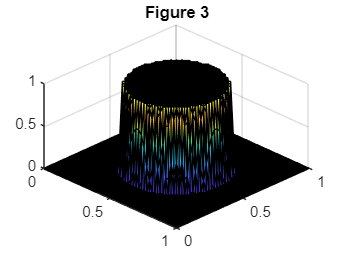

fP0P1 = filter.compute(fun,2);
fP0P1.plot()
view(45,45)
title('Figure 3')

The quadrature included as the second input in filter.compute() is the one used to integrate the input function. The idea is to use an enough high order quadrature concerning the linearity of our input function.

Moreover, we can obtain the same result with other configurations of test (patch dofs) and trial (FE fun vectorial base):

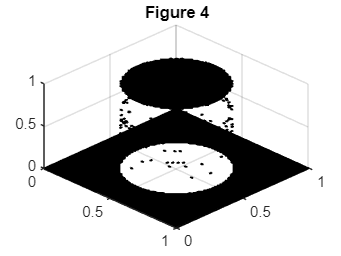

ss.test  = LagrangianFunction.create(mesh,1,'P0');
ss.trial = LagrangianFunction.create(mesh,1,'P0');
filter   = Filter.create(ss);
fP0P0    = filter.compute(fun,2);
fP0P0.plot()
view(45,45)
title('Figure 4')

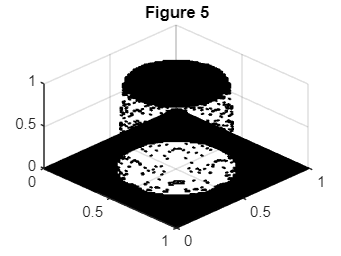


ss.test  = LagrangianFunction.create(mesh,1,'P1');
ss.trial = LagrangianFunction.create(mesh,1,'P0');
filter   = Filter.create(ss);
fP1P0    = filter.compute(fun,2);
fP1P0.plot()
view(45,45)
title('Figure 5')

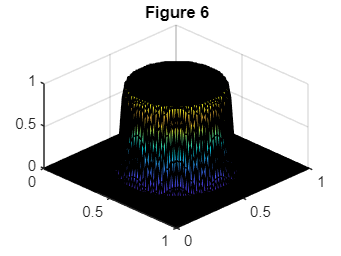


ss.test  = LagrangianFunction.create(mesh,1,'P1');
ss.trial = LagrangianFunction.create(mesh,1,'P1');
filter   = Filter.create(ss);
fP1P1    = filter.compute(fun,2);
fP1P1.plot()
view(45,45)
title('Figure 6')

We can recompute any result with more precision by employing the unfitted function "funLS" instead of "fun". Let's see the P0 to P1 example:

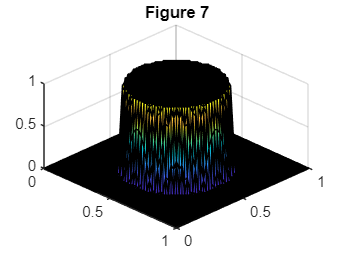

ss.test  = LagrangianFunction.create(mesh,1,'P0');
ss.trial = LagrangianFunction.create(mesh,1,'P1');
filter   = Filter.create(ss);
fP0P1LS  = filter.compute(funLS,2);
fP0P1LS.plot()
view(45,45)
title('Figure 7')

### PDE Filter

Let's create now a PDE filter. This new kind of filter works with two additional parameters:

- Boundary type: Neumann (only filters internal boundaries) or Robin (filters all boundaries).

- Metric: Isotropy or Anisotropy (x and y have different measurement metrics).

Let's start by filtering isotropically just the internal boundaries with this filter:

ss.filterType   = 'PDE';
ss.mesh         = mesh;
ss.boundaryType = 'Neumann';
ss.metric       = 'Isotropy';
filter          = Filter.create(ss);

We can obtain and plot our filtered function (Figure 8) as:

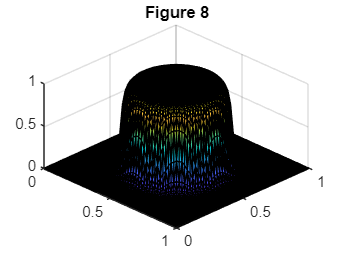

fP1PDE = filter.compute(fun,2);
fP1PDE.plot()
view(45,45)
title('Figure 8')

Another important parameter that can be controlled is the 'epsilon', standing for the radius of influence. The higher the epsilon, the smoother the obtained solution (Figure 9) and, of course, the higher the amount of numerical information lost. Inherently, epsilon must be at least >=minimum mesh size.

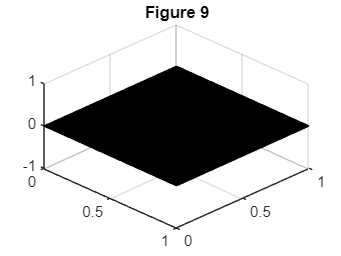

epsilon    = 4*mesh.computeMeanCellSize();
filter.updateEpsilon(epsilon);
fP1highEps = filter.compute(fun,1);
fP1highEps.plot()
view(45,45)
title('Figure 9')

Let's finish by filtering anisotropically the internal boundaries with this filter:

ss.metric       = 'Anisotropy';
ss.CAnisotropic = [100, 0; 0, 0.01];
ss.aniAlphaDeg  = 0;
filter          = Filter.create(ss);

Here, it is necessary to define an expansion matrix CAnisotropic establishing the preferential direction and an aniAlphaDeg angle that rotates this behaviour. In this example, direction X is smoothed with a priority 10000 higher than the corresponding to direction Y. The obtained solution is the following (Figure 10):

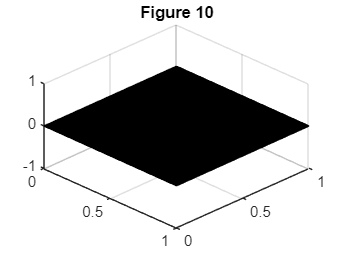

fP1Ani = filter.compute(fun,1);
fP1Ani.plot()
view(45,45)
title('Figure 10')

### Lump filter

Let's finish by creating a lump filter. This filter is essentially a modified version of a FE function projection, where the LHS is lumped before solving the system. Let's see an example with a P1 function:

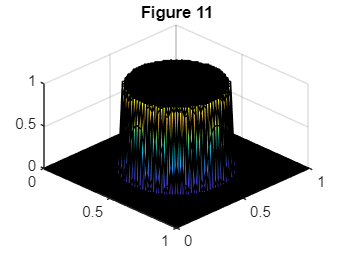

ss.filterType = 'LUMP';
ss.mesh       = mesh;
ss.trial      = LagrangianFunction.create(mesh,1,'P1');
filter        = Filter.create(ss);
fP1Lump       = filter.compute(fun,2);
fP1Lump.plot()
view(45,45)
title('Figure 11')

## Grid convergence analysis

We have observed all the possibilities that Swan incorporates to filter any kind of function. Just to finish, it is interesting to study the precision and the grid convergence for the error of all these filters:

nodesAlongDir = 5:5:110;
nEl           = zeros(length(nodesAlongDir),1);
er00          = zeros(length(nodesAlongDir),1);
er01          = zeros(length(nodesAlongDir),1);
er10          = zeros(length(nodesAlongDir),1);
er11          = zeros(length(nodesAlongDir),1);
ePDE          = zeros(length(nodesAlongDir),1);
erLump        = zeros(length(nodesAlongDir),1);
for i = 1:length(nodesAlongDir)


Let's define the local mesh:

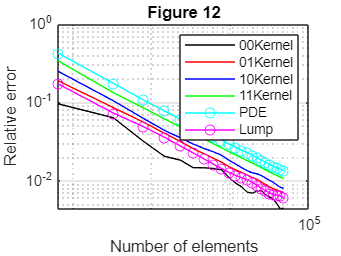

    nX       = nodesAlongDir(i);
    x1       = linspace(0,1,nX);
    x2       = linspace(0,1,nX);
    [xv,yv]  = meshgrid(x1,x2);
    [F,V]    = mesh2tri(xv,yv,zeros(size(xv)),'x');
    m.coord  = V(:,1:2);
    m.connec = F;
    mesh     = Mesh.create(m);

    nEl(i)   = mesh.nelem;

Also the local analytical function:

    s.fHandle = @(x) 1-heaviside((x(1,:,:)-0.5).^2+(x(2,:,:)-0.5).^2-0.3.^2);
    s.ndimf   = 1;
    s.mesh    = mesh;
    fun       = AnalyticalFunction(s);

Now, we will define two integrators to evaluate the error at each iteration:

    refEr = 0.5*Integrator.compute(DDP(fun,fun),mesh,2);

And lastly, let's redefine all filters previously presented:

    ssk.filterType = 'P1';
    ssk.mesh       = mesh;
    ssk.test       = LagrangianFunction.create(mesh,1,'P0');
    ssk.trial      = LagrangianFunction.create(mesh,1,'P0');
    filter         = Filter.create(ssk);
    fP0P0i         = filter.compute(fun,2);

    ssk.test  = LagrangianFunction.create(mesh,1,'P0');
    ssk.trial = LagrangianFunction.create(mesh,1,'P1');
    filter    = Filter.create(ssk);
    fP0P1i    = filter.compute(fun,2);

    ssk.test  = LagrangianFunction.create(mesh,1,'P1');
    ssk.trial = LagrangianFunction.create(mesh,1,'P0');
    filter    = Filter.create(ssk);
    fP1P0i    = filter.compute(fun,2);

    ssk.test  = LagrangianFunction.create(mesh,1,'P1');
    ssk.trial = LagrangianFunction.create(mesh,1,'P1');
    filter    = Filter.create(ssk);
    fP1P1i    = filter.compute(fun,2);

    sspde.filterType   = 'PDE';
    sspde.mesh         = mesh;
    sspde.boundaryType = 'Neumann';
    sspde.metric       = 'Isotropy';
    sspde.trial        = LagrangianFunction.create(mesh,1,'P1');
    filter             = Filter.create(sspde);
    fP1PDEi            = filter.compute(fun,2);

    ssl.filterType = 'LUMP';
    ssl.mesh       = mesh;
    ssl.trial      = LagrangianFunction.create(mesh,1,'P1');
    filter         = Filter.create(ssl);
    fP1Lumpi       = filter.compute(fun,2);

Each relative error is computed as follows:

    sDom.operation = @(xV) fun.evaluate(xV);
    sDom.mesh      = mesh;
    funDom         = DomainFunction(sDom);
    
    er00(i)   = 0.5*Integrator.compute((funDom-fP0P0i).^2,mesh,2)/refEr;
    er01(i)   = 0.5*Integrator.compute((funDom-fP0P1i).^2,mesh,2)/refEr;
    er10(i)   = 0.5*Integrator.compute((funDom-fP1P0i).^2,mesh,2)/refEr;
    er11(i)   = 0.5*Integrator.compute((funDom-fP1P1i).^2,mesh,2)/refEr;
    ePDE(i)   = 0.5*Integrator.compute((funDom-fP1PDEi).^2,mesh,2)/refEr;
    erLump(i) = 0.5*Integrator.compute((funDom-fP1Lumpi).^2,mesh,2)/refEr;
end

The final results are presented in the following plot:

figure()
loglog(nEl,er00,'k',nEl,er01,'r',nEl,er10,'b',nEl,er11,'g',nEl,ePDE,'-oc',nEl,erLump,'-om')
legend('00Kernel','01Kernel','10Kernel','11Kernel','PDE','Lump')
grid on
grid minor
xlabel('Number of elements')
ylabel('Relative error')
title('Figure 12')

## Miss anything?

Feel free to create a new Issue in Swan's GitHub repository with any questions or doubts you may have. We will get back to you as soon as possible!